# V768 - Measuring Vision with Psychophysics

## Lab 9 - Continuous Psychophysics

In previous labs, you've measured visual perception using forced choice experiments that involve showing one or more stimuli to an observer and then obtaining one discrete response.

What if we instead wanted to measure an observer's perception ***continuously***?

In this lab, you'll learn how **continuous psychophysics** can be used to measure perception throughout a trial. Specifically, you'll learn how to analyze data from a continuous target-tracking task, and you'll assess the validity of that task by comparing the results to those of a more traditional forced choice experiment.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Describe a target-tracking experiment from the perspective of a subject.

- Compare and contrast target-tracking experiments and 2AFC experiments using the matched experiments in this lab as examples.

### Questions

- Include and write a caption for the figure in Part A, Step 3. Visualize trial data, "Plot the target and response positions for an example trial" (3-panel figure showing example position data).

- Include and write a caption for the figure in Part A, Step 4. Analyze your data, "Plot CCGs per stimulus condition" (2-panel figure with 4 lines per panel).

- Include and write a caption for the figure in Part A, Step 4. Analyze your data, "Calculate and plot response latency".

- Include and write a caption for the figure in Part B, Step 4. Analyze your data, "Calculate and plot just noticeable difference (JND)".

- Include and write a caption for the figure in Part C. Performance Comparison.

- Do you think these experiments are measuring the same thing? Why or why not?

- Discuss the pros and cons of these two types of tasks.

## Part A. Continuous Target-Tracking

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "tracking", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 16 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("tracking", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

search_pattern = append(participant_id, "*.csv");

% find csv files
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
demo_tracking_2025-03-25_00h18.59.732.csv


**Confirm that all of your data files are listed above.** There should be one file.

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
track_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    col_to_check = find(contains(this_data.Properties.VariableNames,'thisTrialN'),1);
    row_to_remove = isnan(table2array(this_data(:, col_to_check)));
    this_data(row_to_remove,:) = [];  % remove row on expt instructions
    track_data = [track_data; this_data];
end
warning on; clear this_data col_to_check row_to_remove

% display data table size
n_trials = size(track_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 16


### Step 3. Visualize trial data

For this experiment, the stimulus was a two-dimensional Gaussian luminance blob that moved across the screen in a random walk. Across trials, the blob's width varied. (Because the contrast of these blobs depends on their width, contrast also varied.) The participant was tasked with tracking the center of the blob by moving a red dot around the screen with their mouse or trackpad.

For each trial, PsychoPy saved several timecourses (i.e., sets of data per time point): the time in seconds, the target's x and y coordinates in pixels, and the response cursor's x and y coordinates in pixels. Additionally, the blob width per trial was saved.

% extract the target and response positions
target_x = cellfun(@str2num,track_data.blob_x,'UniformOutput',false);
target_y = cellfun(@str2num,track_data.blob_y,'UniformOutput',false);
response_x = cellfun(@str2num,track_data.response_mouse_x,'UniformOutput',false);
response_y = cellfun(@str2num,track_data.response_mouse_y,'UniformOutput',false);

% extract the time of each data point
track_time = cellfun(@str2num,track_data.response_mouse_time,'UniformOutput',false);

% extract the blob width
target_width = track_data.blobWidth;

#### Plot the target and response positions for an example trial

To get a sense of what the data for one trial look like, let's plot the coordinates of the stimulus and response three ways: (1) in xy space, (2) x-position vs. time, and (3) y-position vs. time.

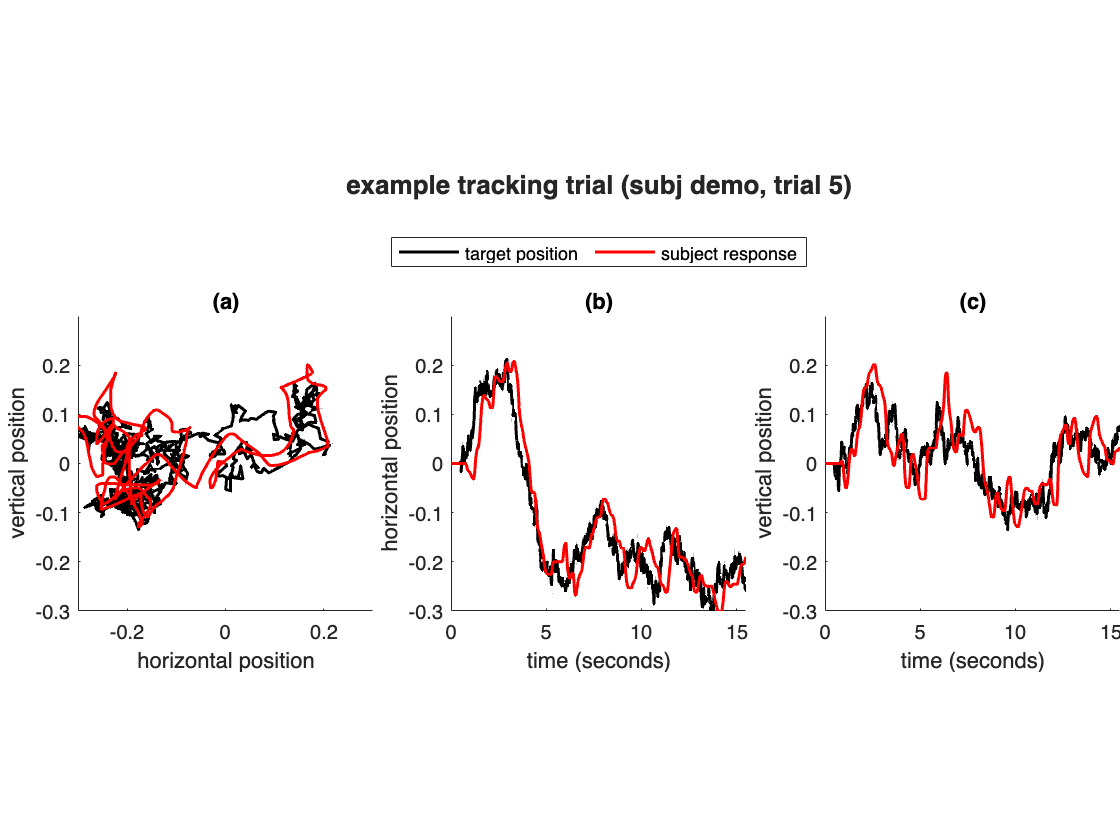

pick_a_trial = 5;  % choose which trial to plot

% plot!
figure;
t = tiledlayout(1,3, 'TileSpacing','tight', 'Padding','tight');
title(t, [sprintf("example tracking trial (subj %s, trial %i)", participant_id, pick_a_trial),""], ...
    'FontWeight','bold');
line_width = 1.5;

ax = nexttile; hold on;
plot(target_x{pick_a_trial},target_y{pick_a_trial},'k','LineWidth',line_width)
plot(response_x{pick_a_trial},response_y{pick_a_trial},'r','LineWidth',line_width)
xlim([-.3,.3]); ylim([-.3,.3]);
axis square; box off;
title("(a)")
xlabel("horizontal position");
ylabel("vertical position");

nexttile; hold on;
plot(track_time{pick_a_trial},target_x{pick_a_trial},'k','LineWidth',line_width);
plot(track_time{pick_a_trial},response_x{pick_a_trial},'r','LineWidth',line_width);
ylim([-.3,.3]);
axis square; box off;
title("(b)")
xlabel("time (seconds)");
ylabel("horizontal position");

nexttile; hold on;
plot(track_time{pick_a_trial},target_y{pick_a_trial},'k','LineWidth',line_width);
plot(track_time{pick_a_trial},response_y{pick_a_trial},'r','LineWidth',line_width);
ylim([-.3,.3]);
axis square; box off;
title("(c)")
xlabel("time (seconds)");
ylabel("vertical position");

lgd = legend(ax, ["target position","subject response"], 'NumColumns',2); 
lgd.Layout.Tile = 'North';

drawnow;

When we show a participant a stimulus, we always expect there to be a time gap before their response because perceiving a stimulus, deciding how to respond, and moving to respond each take time (not necessarily very much time, but more than nothing). A participant could only reliably respond to a stimulus before they actually see it if the stimulus's state is predictable. In this case, the target's motion was random, so we can be confident that there should be a temporal delay (lag) between the target's motion and the response cursor's motion (i.e., the response should lag behind the target in time).

Because of this expected temporal delay, the lines plotted above will likely not match exactly, but if the participant was very good at tracking the target with their cursor, the shape of the plotted lines will look fairly similar. We ultimately want to quantify the participant's ability to track the target, so take a moment to consider the trial data plotted above and ask yourself, **how can we quantify the similarity between the target and response data?**

#### Plot the target velocities for an example trial

First, let's confirm that our target's motion was random. The experiment was designed such that the stimulus **velocity** at each time point should have been randomly sampled from a normal distribution with a mean of zero. We can confirm that the velocities are normally distributed by plotting their actual distribution along with the distribution from which they should have been drawn.

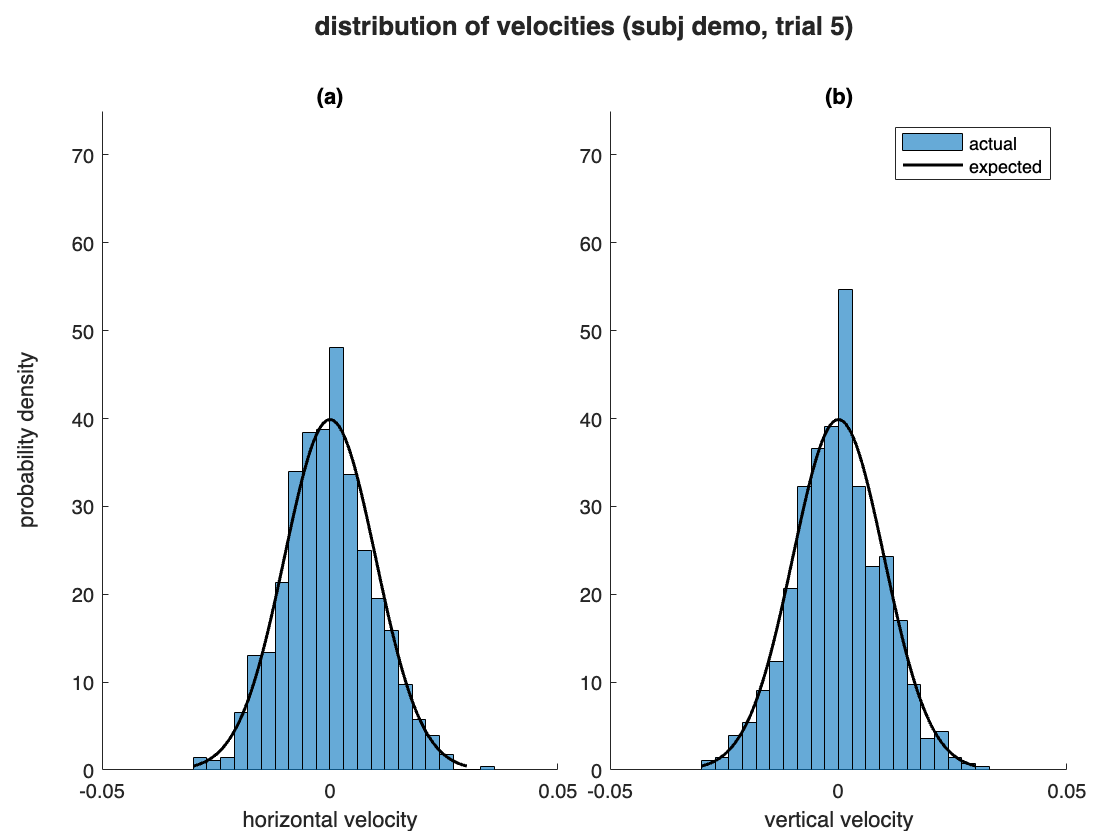

% get expected distribution of velocity values
vel_pdf.sigma = track_data.sig(1);
vel_pdf.x = linspace(-3*vel_pdf.sigma, 3*vel_pdf.sigma, 100);
vel_pdf.y = normpdf(vel_pdf.x, 0, vel_pdf.sigma);

% plot!
figure;
t = tiledlayout(1,2, 'TileSpacing','tight', 'Padding','compact');
title(t, [sprintf("distribution of velocities (subj %s, trial %i)", participant_id, pick_a_trial),""], ...
    'FontWeight','bold');

nexttile; hold on;
histogram(diff(target_x{pick_a_trial}), 'Normalization','pdf')
plot(vel_pdf.x, vel_pdf.y, 'k','LineWidth',line_width)
xlim([-0.05,0.05]); ylim([0,75]); box off;
title("(a)");
xlabel("horizontal velocity");
ylabel(["probability density",""]);

nexttile; hold on;
histogram(diff(target_y{pick_a_trial}), 'Normalization','pdf')
plot(vel_pdf.x, vel_pdf.y, 'k','LineWidth',line_width)
xlim([-0.05,0.05]); ylim([0,75]); box off;
title("(b)")
xlabel("vertical velocity");
legend(["actual","expected"], 'Location','northeast');

drawnow;

**What do you think? **Were the actual velocities randomly drawn from the expected distribution?

#### Plot the target and response velocities for an example trial

Next, let's take a look at the velocity timecourses.

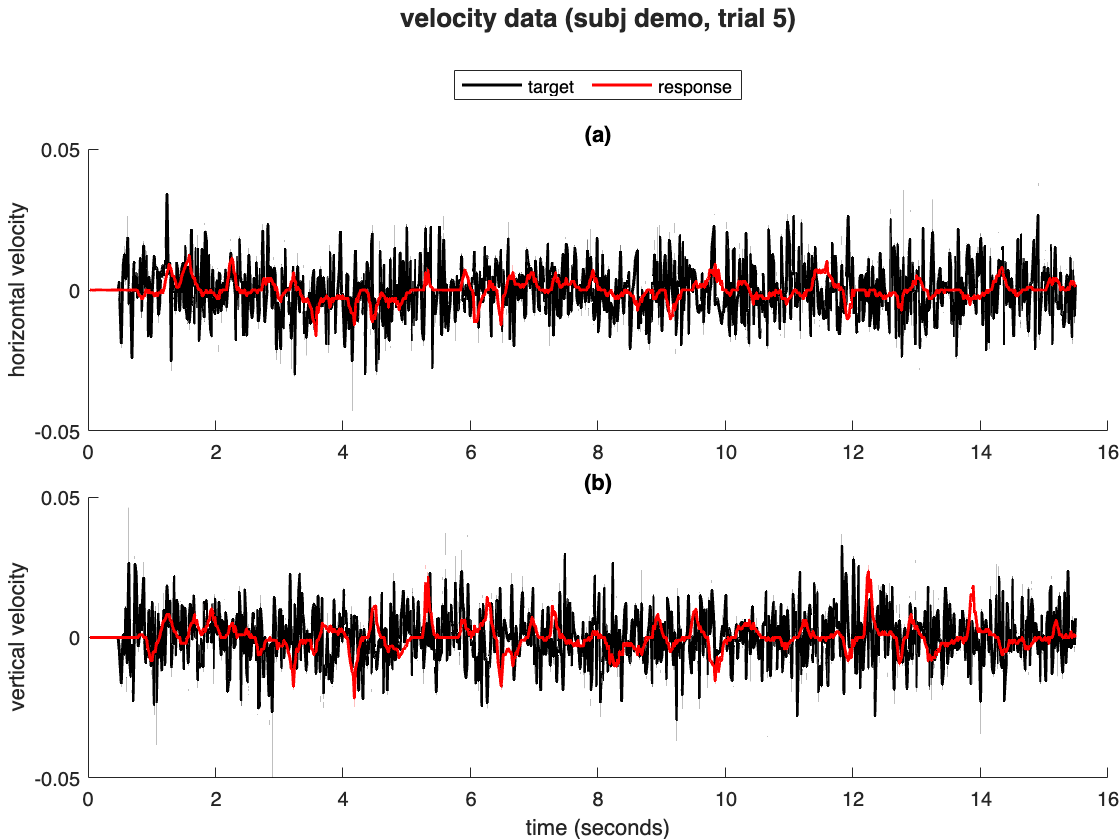

% get velocities for that trial
ex_vel.targ_x = diff(target_x{pick_a_trial});
ex_vel.targ_y = diff(target_y{pick_a_trial});
ex_vel.resp_x = diff(response_x{pick_a_trial});
ex_vel.resp_y = diff(response_y{pick_a_trial});
ex_vel.time = track_time{pick_a_trial}(2:end);

% plot!
figure;
t = tiledlayout(2,1, 'TileSpacing','tight', 'Padding','tight');
title(t, [sprintf("velocity data (subj %s, trial %i)", participant_id, pick_a_trial),""], ...
    'FontWeight','bold');
line_width = 1.5;

ax = nexttile; hold on;
plot(ex_vel.time, ex_vel.targ_x,'k','LineWidth',line_width);
plot(ex_vel.time, ex_vel.resp_x,'r','LineWidth',line_width);
ylim([-0.05,0.05]); box off;
title("(a)")
ylabel("horizontal velocity");

nexttile; hold on;
plot(ex_vel.time, ex_vel.targ_y,'k','LineWidth',line_width);
plot(ex_vel.time, ex_vel.resp_y,'r','LineWidth',line_width);
ylim([-0.05,0.05]); box off;
title("(b)")
xlabel("time (seconds)");
ylabel("vertical velocity");

lgd = legend(ax, ["target","response"], 'NumColumns',2);
lgd.Layout.Tile = 'North';

drawnow;

### Step 4. Analyze your data

Due to the randomness of the target's motion and the time required for the participant to perceive and respond to a visual stimulus, the movement of the response cursor should lag behind the movement of the target, even for the most accurate participant. To account for that lag, we can take the stimulus and response time series, shift the response time series backwards and forwards in time, and compute the similarity between the two time series as a function of that relative temporal shift. In other words, we can calculate the **cross-correlation** of the target and response data.

**Cross-correlation** measures the similarity between two series of values as a function of the displacement of one relative to the other. Essentially. computing cross-correlation involves finding the correlation between series A and multiple shifted (lagged) copies of series B.

In this case, because target **velocity** is randomly distributed, we want to cross-correlate the target and response velocitties.

#### Calculate velocity cross-correlations

Let's calculate the velocity cross-correlation for each trial and each dimension (horizontal and vertical) so that we can make some **cross-correllograms (CCGs)**. (A CCG is simply a plot showing a cross-correlation.)

% define function for calculating CCGs
calculate_velocity_ccg = @(x,y) xcorr(diff(x),diff(y),120,'normalized');

% calculate CCGs for horizontal axis
ccg_x = cell2mat(cellfun(calculate_velocity_ccg, ...
    response_x, target_x, 'UniformOutput',false));

% calculate CCGs for vertical axis
ccg_y = cell2mat(cellfun(calculate_velocity_ccg, ...
    response_y, target_y, 'UniformOutput',false));

% calculate time in seconds per CCG value
frame_rate = round(1./mean(diff(track_time{1}))).';
ccg_lag = (-120:120)/frame_rate;

#### Plot CCGs for an example trial

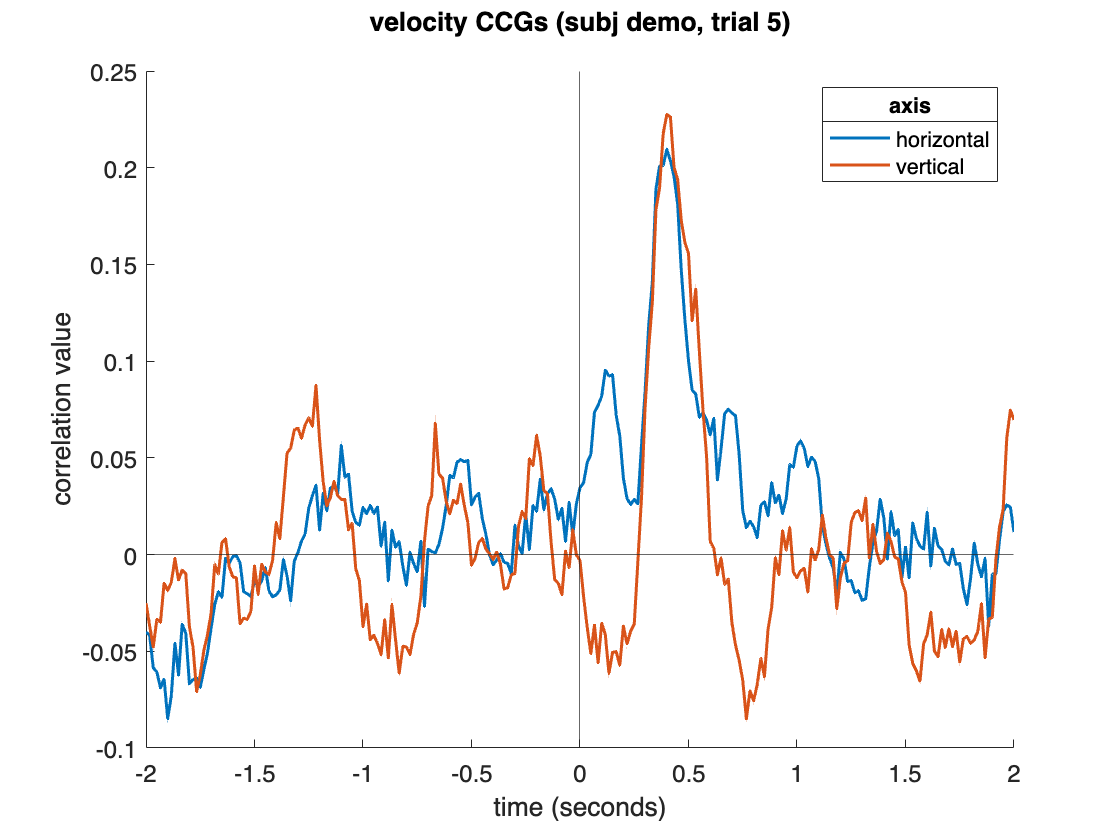

figure; hold on
xline(0); yline(0);
plot(ccg_lag, ccg_x(pick_a_trial,:), 'LineWidth',line_width)
plot(ccg_lag, ccg_y(pick_a_trial,:), 'LineWidth',line_width)
box off; set(gca, 'FontSize',12)
title([sprintf("velocity CCGs (subj %s, trial %i)", participant_id, pick_a_trial),""])
xlabel("time (seconds)"); ylabel("correlation value")
lgd = legend(["","", "horizontal", "vertical"]);
title(lgd, "axis")

drawnow;

#### Plot each trial's CCGs

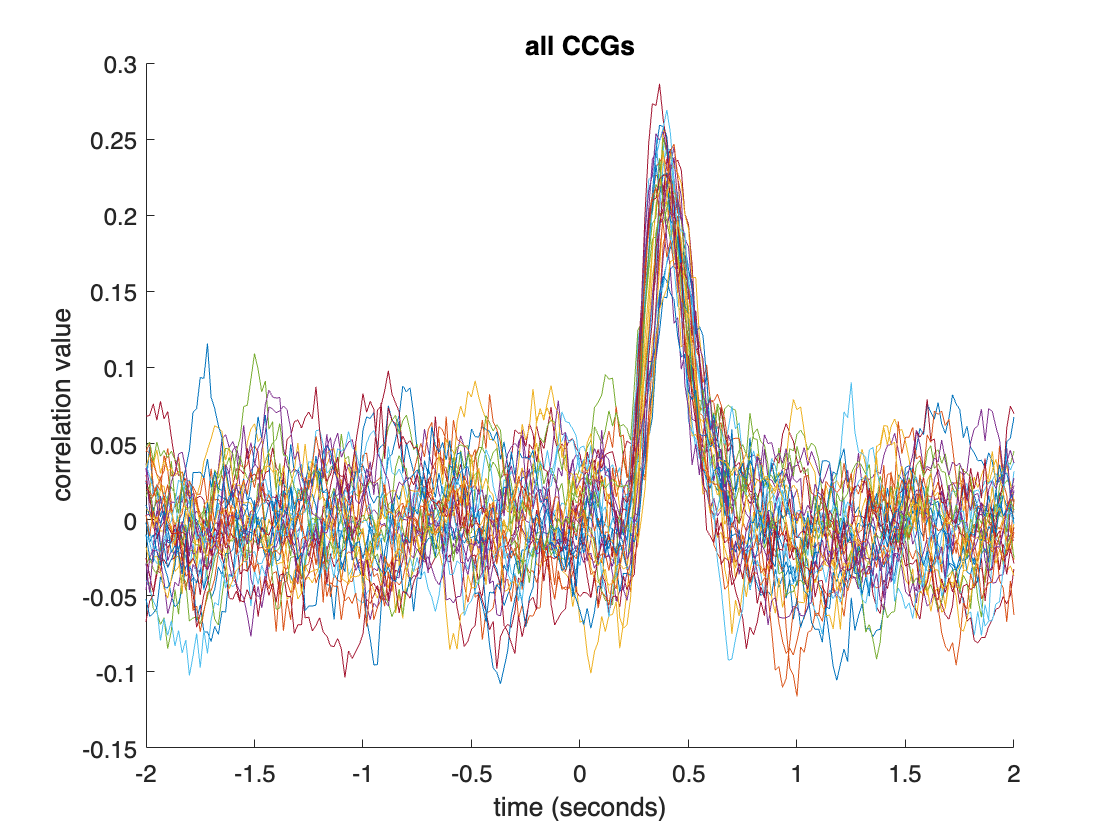

figure; hold on
plot(ccg_lag, ccg_x)
plot(ccg_lag, ccg_y)
box off; set(gca, 'FontSize',12)
title("all CCGs")
xlabel("time (seconds)")
ylabel("correlation value")

drawnow;

#### Average CCGs per stimulus condition

expt_results = grpstats(table(ccg_x, ccg_y, target_width), "target_width");
expt_results = renamevars(expt_results, "GroupCount", "n_trials");
expt_results.Properties.RowNames = {};

mean_ccg_x = expt_results.mean_ccg_x.';
mean_ccg_y = expt_results.mean_ccg_y.';
targ_levels = expt_results.target_width;

#### Plot CCGs per stimulus condition

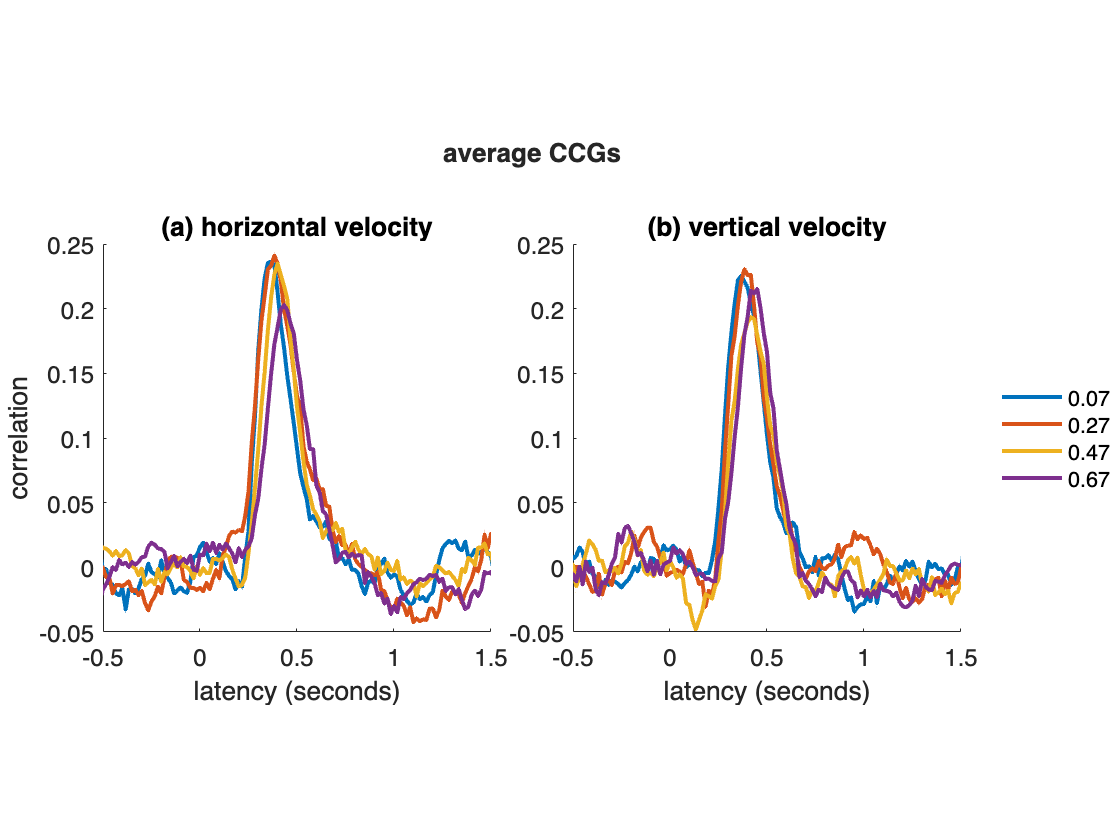

figure;
t = tiledlayout(1,2, 'TileSpacing','tight', 'Padding','tight');
title(t, ["average CCGs",""], 'FontWeight','bold');

ax = nexttile;
plot(ccg_lag, mean_ccg_x,'LineWidth',2)
box off; axis square; set(gca,'FontSize',12)
xlim([-.5,1.5])
title("(a) horizontal velocity")
xlabel("latency (seconds)"); ylabel("correlation");
set(gca,'FontSize',12)

nexttile;
plot(ccg_lag, mean_ccg_y,'LineWidth',2)
box off; axis square; set(gca,'FontSize',12)
xlim([-.5,1.5])
title("(b) vertical velocity")
xlabel("latency (seconds)");

lgd = legend(ax, string(num2str(targ_levels)).', 'Box','off');
lgd.Layout.Tile = 'East';

drawnow;

**What do you notice?** Are the CCGs for the horizontal and vertical axes similar or different? Does performance change with blob width? If so, how?

#### Calculate and plot response latency

**How can we *****quantitatively***** compare performance across conditions? **There are three main CCG features that we can use to characterize performance:

- the peak correlation value (i.e., peak height),

- the lag value at that peak (i.e., response latency), and

- the width (e.g., the full width of the CCG at half height).

Here, let's find the peak of each CCG so that we can find the **response latency** per condition.

[ccg_peak, peak_frame] = max(mean_ccg_x);
response_latency = ccg_lag(peak_frame).';
disp(array2table(response_latency, "RowNames",string(targ_levels)))

            response_latency
            ________________

    0.07        0.36667     
    0.27        0.38333     
    0.47            0.4     
    0.67        0.43333     



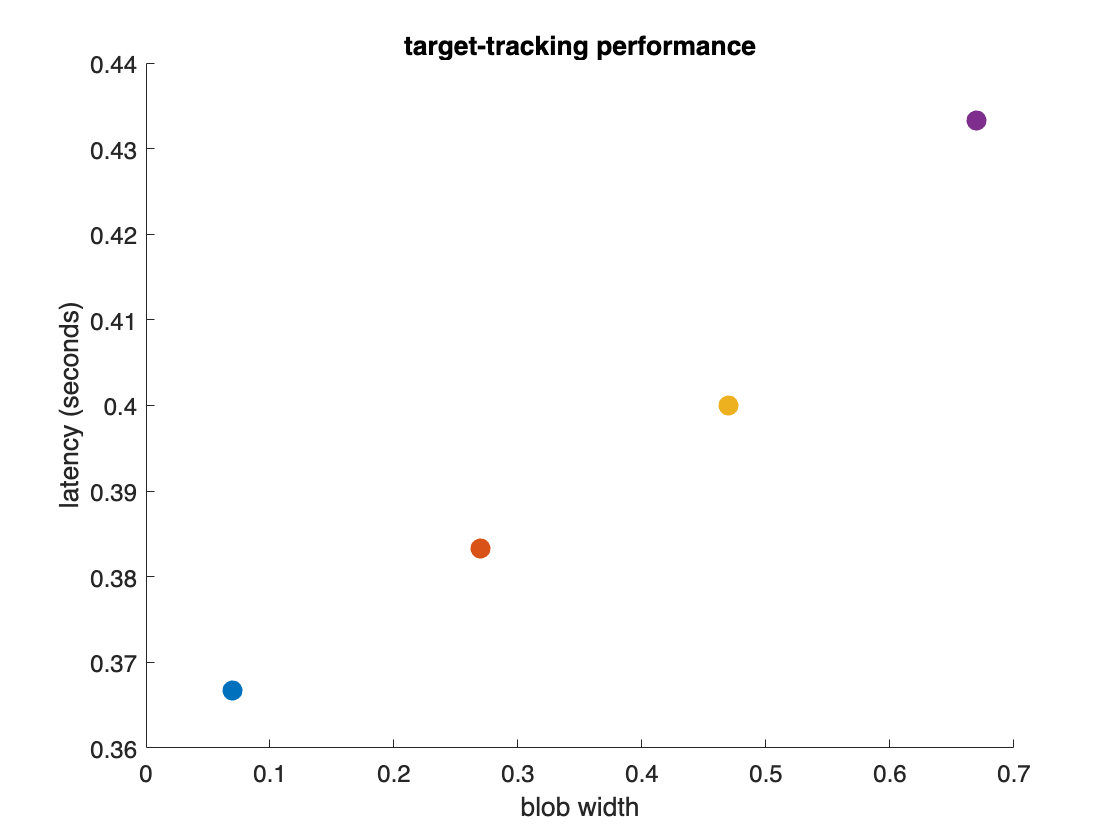

figure; hold on;
for ii=1:length(targ_levels)
    plot(targ_levels(ii),response_latency(ii),'.','MarkerSize',30)
end
title("target-tracking performance")
xlabel("blob width"); ylabel("latency (seconds)");
set(gca,'FontSize',12);

drawnow;

## Part B. Traditional Forced Choice Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "2afc", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 144 trials.

**IMPORTANT:** You need to run the experiment **THREE** times.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("2afc", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

search_pattern = append(participant_id, "*.csv");

% find csv files
file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
file_info = struct2table(file_info);
file_info.name = string(file_info.name);
file_info.folder = string(file_info.folder);

% find files for given participant
file_mask = startsWith(file_info.name, participant_id);
file_info = file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(file_info.name)
end

data files found:
    "demo_Bonnen2015_2afc_2025-03-24_16h55.36.408.csv"
    "demo_Bonnen2015_2afc_2025-03-24_16h58.34.387.csv"
    "demo_Bonnen2015_2afc_2025-03-24_17h14.42.856.csv"



**Confirm that all of your data files are listed above.** There should be **THREE** files (1 for each run).

#### Load and merge data tables

% build full paths
file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    file_info.folder, file_info.name);

% load data and stack it into one table
warning off;
choice_data = table;
for ff = 1:n_files
    this_data = readtable(file_info.path(ff));
    col_to_check = find(contains(this_data.Properties.VariableNames,'thisTrialN'),1);
    row_to_remove = isnan(table2array(this_data(:, col_to_check)));
    this_data(row_to_remove,:) = [];  % remove row on expt instructions
    choice_data = [choice_data; this_data];
end
warning on; clear this_data col_to_check row_to_remove

% display data table size
n_trials = size(choice_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 432


### Step 3. Visualize trial data

For this experiment, the stimuli were again two-dimensional Gaussian luminance blobs of varying widths. Per trial, two stimuli were shown, each in a different time interval. The reference blob (shown in the first time interval) always appeared at the center of the screen, and the horizontal position of the test blob (shown in the second time interval) varied across trials.

For each trial, PsychoPy saved the blob width, the horizontal offset of the test stimulus, and the participant's response per trial. The responses were stored as 'left' or 'right'.

% stash the stimulus condition per trial
stim_width = choice_data.blobWidth;
stim_offset = choice_data.offset;

% convert the response key to 1 for right and 0 for left
choice = strcmp(choice_data.key_resp_keys,'right');

#### Plot the response per trial

Let's take a look at the data for each trial. Plot the horizontal offset, with the color and symbol of each marker indicating the participant's choice.

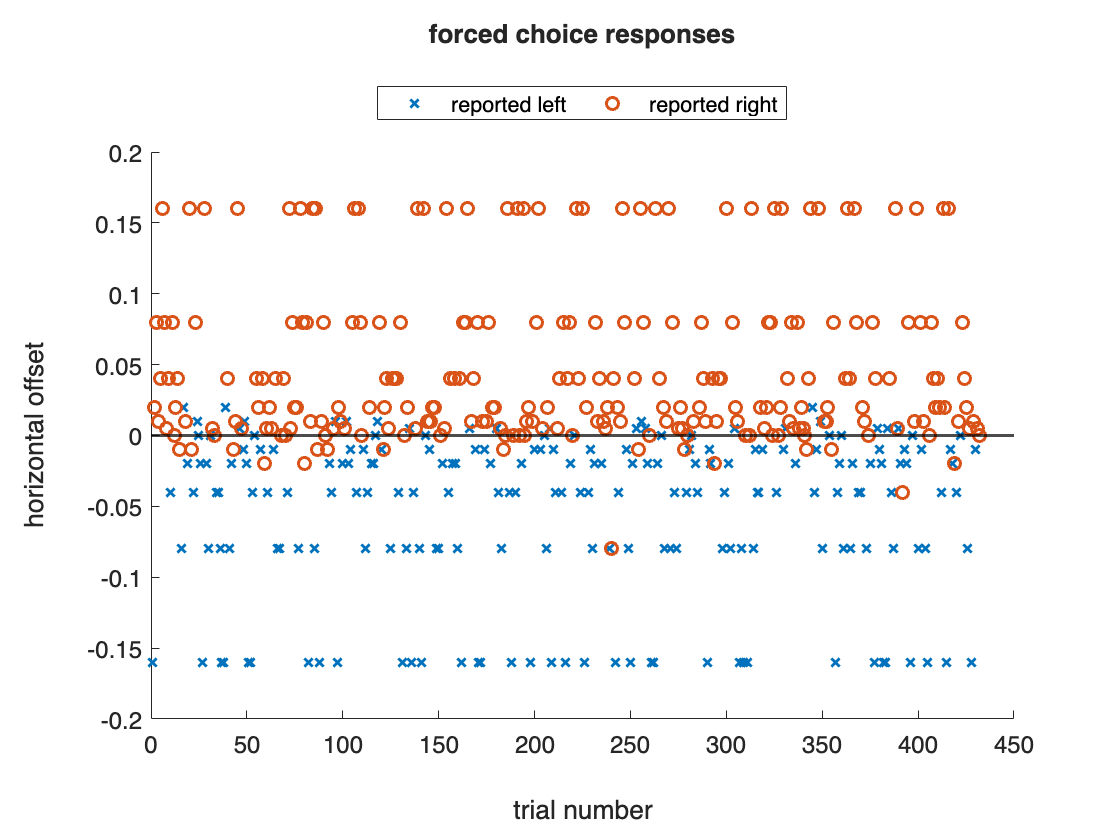

figure; t = tiledlayout(1,1);
title(t, ["forced choice responses",""], 'FontWeight','bold')

nexttile; hold on;
yline(0, 'k', 'LineWidth',1.5)

trials = 1:n_trials;
plot(trials(choice==0),stim_offset(choice==0), 'x', 'LineWidth',1.5)
plot(trials(choice==1),stim_offset(choice==1), 'o', 'LineWidth',1.5)

set(gca,'FontSize',12)
xlabel(["","trial number"]); ylabel(["horizontal offset",""]);
lgd = legend(["","reported left","reported right"], 'NumColumns',2);
lgd.Layout.Tile = 'North';

drawnow;

### Step 4. Analyze your data

#### Average responses per stimulus condition

For each combination of blob width and horizontal offset values, let's determine the probability that you reported a positive offset (i.e., that you chose 'right').

% average across responses per condition
choice_results = table(choice, stim_offset, stim_width, ...
    'VariableNames',["response", "offset", "blob_width"]);
choice_results = grpstats(choice_results, ["offset", "blob_width"]);
choice_results = renamevars(choice_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "prob_chose_pos"]);
choice_results.Properties.RowNames = {};

% stash stimulus levels & counts
stim_width_levels = unique(choice_results.blob_width);
n_stim_width = length(stim_width_levels);

#### Plot performance per stimulus condition

Let's plot these probabilities and check out the resulting curves.

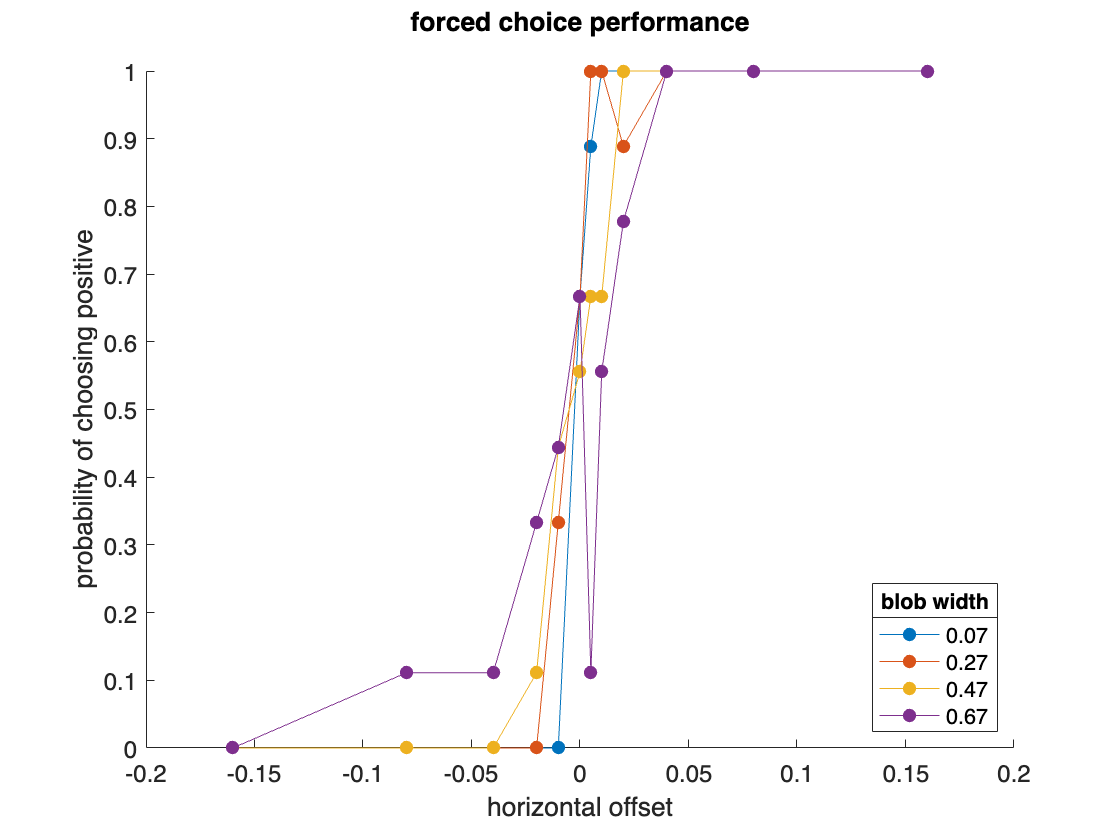

figure; clf; hold on
for i_width = 1:n_stim_width
    idx = choice_results.blob_width == stim_width_levels(i_width);
    plot(choice_results.offset(idx), choice_results.prob_chose_pos(idx), ...
        '.-', 'MarkerSize',20);
end
set(gca,'FontSize',12);
title(["forced choice performance",""])
xlabel("horizontal offset"); ylabel("probability of choosing positive");
lgd = legend(string(stim_width_levels), 'Location','southeast');
title(lgd, "blob width");

drawnow

#### Fit psychometric curves

In previous labs, we covered how to fit psychometric curves to data in order to summarize an observer's performance on a task. Let's fit this data so that we can get closer to having one number per blob width.

init_params = [0,1,0,0];
choice_params = nan(n_stim_width, length(init_params));
opts = optimset('Display','off');
for i_width = 1:n_stim_width
    idx = choice_results.blob_width == stim_width_levels(i_width);
    [choice_params(i_width,:), neg_log_likelihood] = fmincon(@(params) ...
        negLogLikelihood(params,...
        choice_results.offset(idx),...
        choice_results.prob_chose_pos(idx).*choice_results.n_trials(idx),...
        choice_results.n_trials(idx)), init_params,...
        [],[],[],[],[-.2,0,0,0],[.2,100,.5,.5],[],opts);
end
choice_params = array2table(choice_params, 'RowNames',string(stim_width_levels), ...
    'VariableNames',["mu","sigma","gamma","lambda"]);
disp(choice_params)

                mu           sigma        gamma         lambda  
            ___________    _________    __________    __________

    0.07    -0.00099779     0.004041     9.599e-09    1.6293e-08
    0.27     -0.0058312    0.0064007     9.989e-06      0.020511
    0.47      -0.002762     0.015255    9.9948e-06     9.973e-06
    0.67      0.0035478     0.027159      0.062052    2.8046e-08



#### Calculate and plot just noticeable difference (JND)

To summarize performance with a single number per blob width, let's calculate the JND associated with each width.

jnd = choice_params.sigma/sqrt(2);
disp(array2table(jnd, "VariableNames","JND", ...
    "RowNames",string(stim_width_levels)))

               JND   
            _________

    0.07    0.0028574
    0.27     0.004526
    0.47     0.010787
    0.67     0.019205



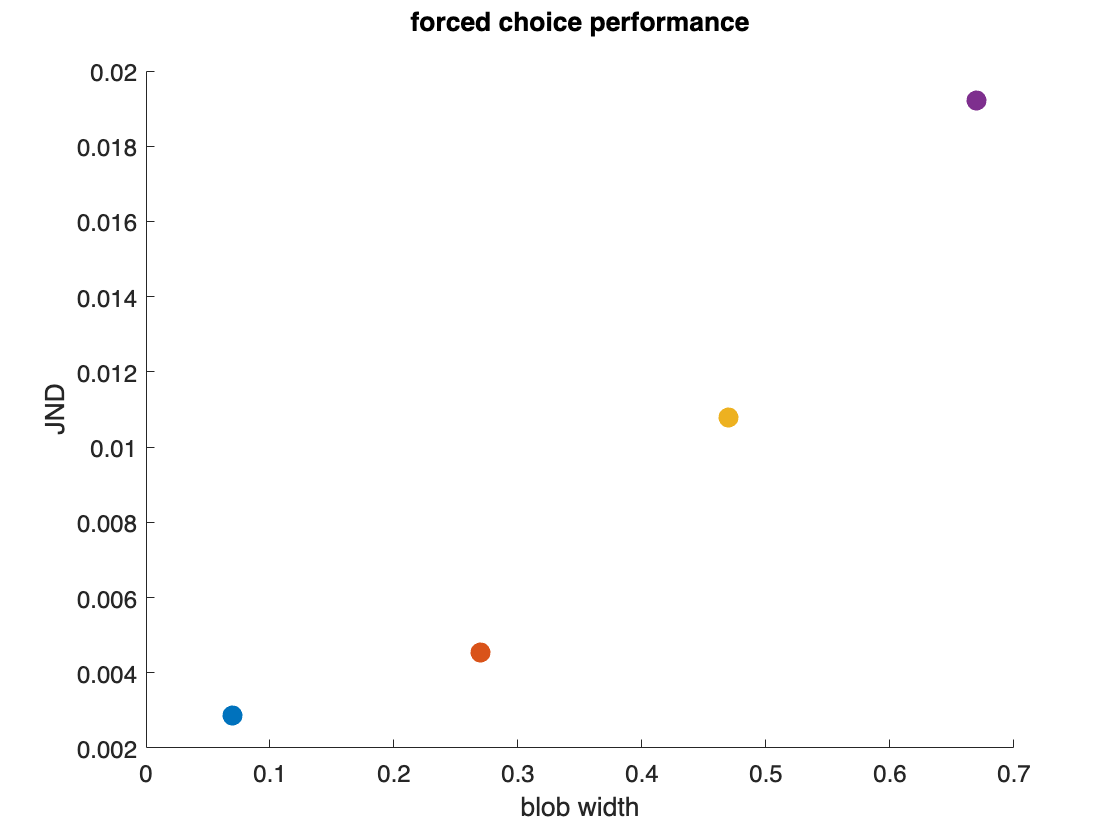

figure; hold on;
for ii=1:n_stim_width
    plot(stim_width_levels(ii),jnd(ii),'.','MarkerSize',30)
end
set(gca,'FontSize',12);
title(["forced choice performance",""])
xlabel("blob width"); ylabel("JND");

drawnow;

## Part C. Performance Comparison

We've now summarized performance on both the target-tracking and forced choice experiments. For the target-tracking task, we computed the response latency per blob width, and for the forced choice task, we computed the JND per blob width.

### Step 1. Visually compare results

In order to determine whether these experiments give us comparable results, let's first plot those two sets of numbers against one another.

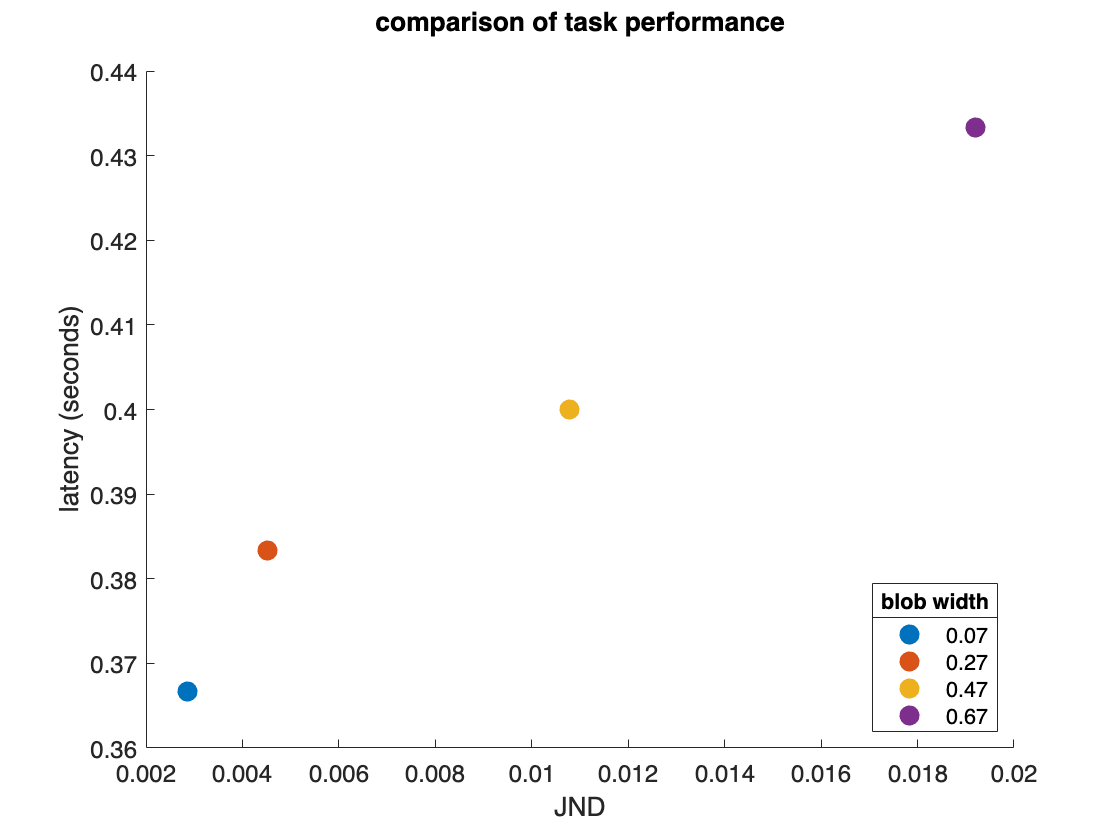

figure(); hold on;
for ii=1:n_stim_width
    plot(jnd(ii),response_latency(ii),'.','MarkerSize',30)
end
set(gca,'FontSize',12)
title(["comparison of task performance",""])
xlabel("JND"); ylabel("latency (seconds)");
lgd = legend(string(stim_width_levels), 'Location','southeast');
title(lgd, "blob width");

drawnow;

**What do you see? **Is there a systematic relationship between JND and response latency? Are these two sets of results more similar or different?

### Step 2. Quantitatively compare results

Now that we have a rough sense of how the results of these two experiments compare, let's calculate the correlation between the measured response latencies and JNDs.

c = corr(jnd(:), response_latency(:));
fprintf("correlation = %.5f", c);

correlation = 0.98844

**What do you think?** Are the target-tracking and forced choice results correlated with one another? Can we use continuous psychophysics instead of the more traditional forced choice task and obtain similar results?